# Getting started with bombcell

## Set paths

Toy dataset location you can play around with. This only has a few units to make it lightweight and easy to load.

toy_dataset_location = '/home/julie/Downloads/kilosort4-20241127T195144Z-001/kilosort4/';%[fileparts(matlab.desktop.editor.getActiveFilename), filesep, 'toy_data', filesep];

These paths below are the paths you will need to input to load data and save the computed quality metrics / ephys properties. Here we are leaving ephysRawFile as "NaN" to not load raw data (it is too cumbersome to store these large files on github). All metrics relating to raw data (amplitude, signal to noise ratio) will not be computed. 

parent_directory = 'X:\Neuro-Leventhal\data\ChoiceTask';
summary_xls = 'ProbeSite_Mapping_MATLAB.xlsx';
summary_xls_dir = 'X:\Neuro-Leventhal\data\ChoiceTask\Probe Histology Summary';
summary_xls = fullfile(summary_xls_dir, summary_xls);
sessions_to_ignore = {'R0378_20210507a', 'R0326_20191107a', 'R0425_20220728a', 'R0425_20220816b', 'R0427_20220920a','R0427_20220919a' }; % R0425_20220728a debugging because the intan side was left on for 15 hours;

ephysKilosortPath = 'X:\Neuro-Leventhal\data\ChoiceTask\R0492\R0492-rawdata\R0492_20230725a\R0492_20230725_ChStandard_230725_143742\kilosort42';
ephysRawFile = 'X:\Neuro-Leventhal\data\ChoiceTask\R0492\R0492-rawdata\R0492_20230725a\R0492_20230725_ChStandard_230725_143742\amplifier.dat'; % path to your raw .bin or .dat data
ephysMetaDir = ''; % path to your .meta or .oebin meta file
savePath = 'X:\Neuro-Leventhal\data\ChoiceTask\R0492\R0492-rawdata\R0492_20230725a\R0492_20230725_ChStandard_230725_143742\kilosort42\qMetrics'; % where you want to save the quality metrics 

Two parameters to pay attention to: the kilosort version (change to kilosortVersion = 4 if you are using kilosort4) and the gain_to_uV scaling factor (this is the scaling factor to apply to your data to get it in microVolts).

kilosortVersion = 4; % if using kilosort4, you need to have this value kilosertVersion=4. Otherwise it does not matter. 
gain_to_uV = 0.195; % use this if you are not using spikeGLX or openEphys to record your data. this value, 
% when mulitplied by your raw data should convert it to  microvolts. 

## Load data

This function loads are your ephys data. Use this function rather than any custom one as it handles zero-indexed values in a particular way. 

[spikeTimes_samples, spikeClusters, templateWaveforms, templateAmplitudes, pcFeatures, ...
    pcFeatureIdx, channelPositions] = bc.load.loadEphysData(ephysKilosortPath, savePath);

## Run quality metrics

#### Set your paramaters. 

These define both how you will run quality metrics and how thresholds will be applied to quality metrics to classify units into good/MUA/noise/non-axonal. This function loads default, permissive values. It's highly recommended for you to iteratively tweak these values to find values that suit your particular use case! 

param = bc.qm.qualityParamValues(ephysMetaDir, ephysRawFile, ephysKilosortPath, gain_to_uV, kilosortVersion);

#### Pay particular attention to `param.nChannels`

`param.nChannels` must correspond to the total number of channels in your raw data, including any sync channels. For Neuropixels probes, this value should typically be either 384 or 385 channels. `param.nSyncChannels` must correspond to the number of sync channels you recorded. This value is typically 1 or 0.

param.nChannels = 64;
param.nSyncChannels = 0;

% if using SpikeGLX, you can use this function: 
if ~isempty(ephysMetaDir)
    if endsWith(ephysMetaDir.name, '.ap.meta') %spikeGLX file-naming convention
        meta = bc.dependencies.SGLX_readMeta.ReadMeta(ephysMetaDir.name, ephysMetaDir.folder);
        [AP, ~, SY] = bc.dependencies.SGLX_readMeta.ChannelCountsIM(meta);
        param.nChannels = AP + SY;
        param.nSyncChannels = SY;
    end
end

#### Run all your quality metrics! 

This function runs all quality metrics, saves the metrics in your savePath folder and outputs some global summary plots that can give you a good idea of how things went. 


 Removed 1604 spike duplicates out of 2178513 total spikes. 

 Extracting quality metrics from X:\Neuro-Leventhal\data\ChoiceTask\R0493\R0493-rawdata\R0493_20230728a\R0493_20230728_Testing_230728_101242\amplifier.dat ... 

   Finished 50 / 67 units.
   Finished 67 / 67 units.
 Finished extracting quality metrics from X:\Neuro-Leventhal\data\ChoiceTask\R0493\R0493-rawdata\R0493_20230728a\R0493_20230728_Testing_230728_101242\amplifier.dat
 Saved quality metrics from X:\Neuro-Leventhal\data\ChoiceTask\R0493\R0493-rawdata\R0493_20230728a\R0493_20230728_Testing_230728_101242\amplifier.dat to X:\Neuro-Leventhal\data\ChoiceTask\R0493\R0493-rawdata\R0493_20230728a\R0493_20230728_Testing_230728_101242\kilosort4b\qMetrics 


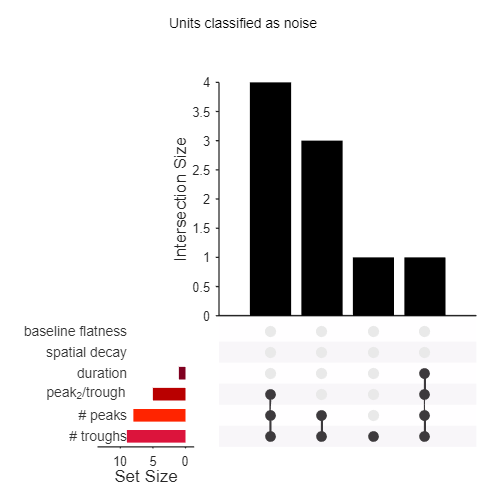

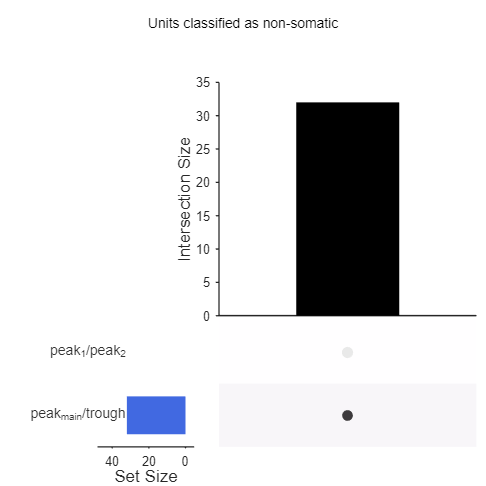

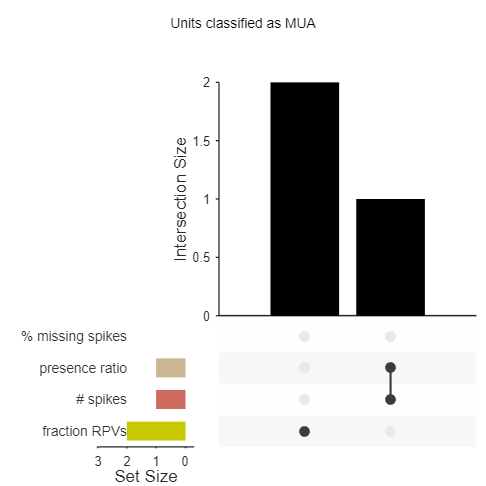

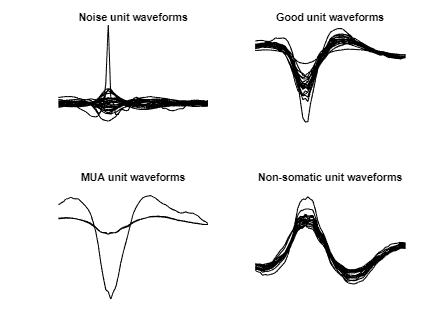

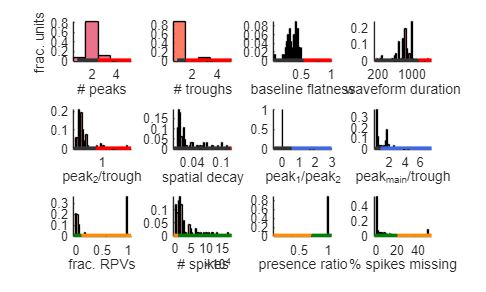

[qMetric, unitType] = bc.qm.runAllQualityMetrics(param, spikeTimes_samples, spikeClusters, ...
        templateWaveforms, templateAmplitudes, pcFeatures, pcFeatureIdx, channelPositions, savePath);

## Inspect

After running quality metrics, espacially the first few times, it's a good idea to inspect your data and the quality metrics using the built-in GUI. Use your keyboard to navigate the GUI: 

- left/right arrow : toggle between units 

- u  : brings up a input dialog to enter the unit you want to go to

- g  : go to next good unit 

- m : go to next multi-unit 

- n  : go to next noise unit

- a  : go to next non-somatic unit ("a" is for axonal)

- up/down arrow : toggle between time chunks in the raw data

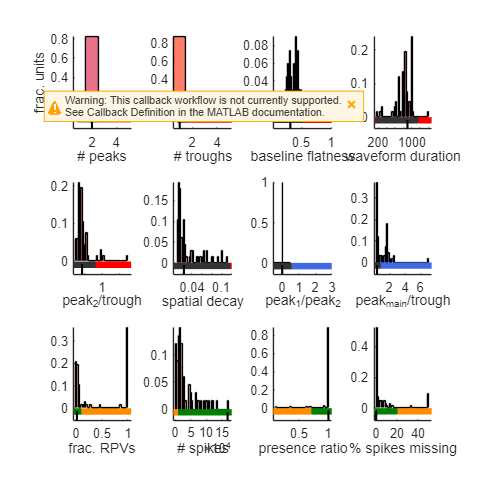

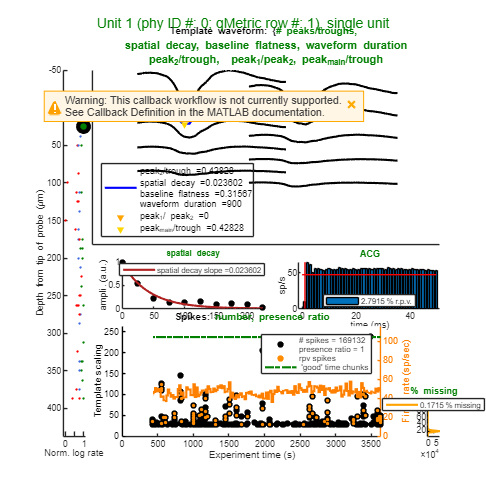

bc.load.loadMetricsForGUI;

unitQualityGuiHandle = bc.viz.unitQualityGUI_synced(memMapData, ephysData, qMetric, forGUI, rawWaveforms, ...
    param, probeLocation, unitType, loadRawTraces);

## Examples

#### Get the quality metrics for one unit

This is an example to get the quality metric for the unit with the original kilosort and phy label of xx (0-indexed), which corresponds to the unit with qMetric.clusterID == xx + 1, and to qMetric.phy_clusterID == xx . This is *NOT NECESSARILY* the (xx + 1)th row of the structure qMetric - some of the  clusters that kilosort outputs are empty, because they were dropped in the last stages of the algorithm. These empty clusters are not included in the qMetric structure.

There are two ways to do this: 

1:


original_id_we_want_to_load = 0;
id_we_want_to_load_1_indexed = original_id_we_want_to_load + 1; 
number_of_spikes_for_this_cluster = qMetric.nSpikes(qMetric.clusterID == id_we_want_to_load_1_indexed);

or 2:

original_id_we_want_to_load = 0;
number_of_spikes_for_this_cluster = qMetric.nSpikes(qMetric.phy_clusterID == original_id_we_want_to_load);

#### Get the unit labels 

The output of `unitType = getQualityUnitType(param, qMetric);` gives  the unitType in a number format. 1 indicates good units, 2 indicates mua units, 3  indicates non-somatic units and 0 indciates noise units (see below) 

 
goodUnits = unitType == 1;
muaUnits = unitType == 2;
noiseUnits = unitType == 0;
nonSomaticUnits = unitType == 3; 

% example: get all good units number of spikes
all_good_units_number_of_spikes = qMetric.nSpikes(goodUnits);

% (for use with another language: output a .tsv file of labels. You can then simply load this) 
label_table = table(unitType);
writetable(label_table,[savePath filesep 'templates._bc_unit_labels.tsv'],'FileType', 'text','Delimiter','\t');  
      

## Run ephys properties

Optionally get ephys properties for your cell. Bombcell will also attempt to classify your data if it is (a) from the cortex or striatum and (b) you specify this in the "region" variable.

rerunEP = 0;
region = ''; % options include 'Striatum' and 'Cortex'
[ephysProperties, unitClassif] = bc.ep.runAllEphysProperties(ephysKilosortPath, savePath, rerunEP, region);


 Extracting ephys properties ... 
   Finished 67 / 67 units.
 Finished extracting ephys properties
 Saved ephys properties to X:\Neuro-Leventhal\data\ChoiceTask\R0493\R0493-rawdata\R0493_20230728a\R0493_20230728_Testing_230728_101242\kilosort4b\qMetrics 
